# Laboratorio No. 4 - Cinemática Directa - PhantomX Pincher - ROS - Robótica

INTEGRANTES:

Victor Manuel Dávila Castañeda.

Manuel Felipe Carranza Montenegro.

clc;
clear;
addpath('/Users/macuser/MATLAB-Drive/RVC1/rvctools/');

**Robot PhantomX Pincher.**

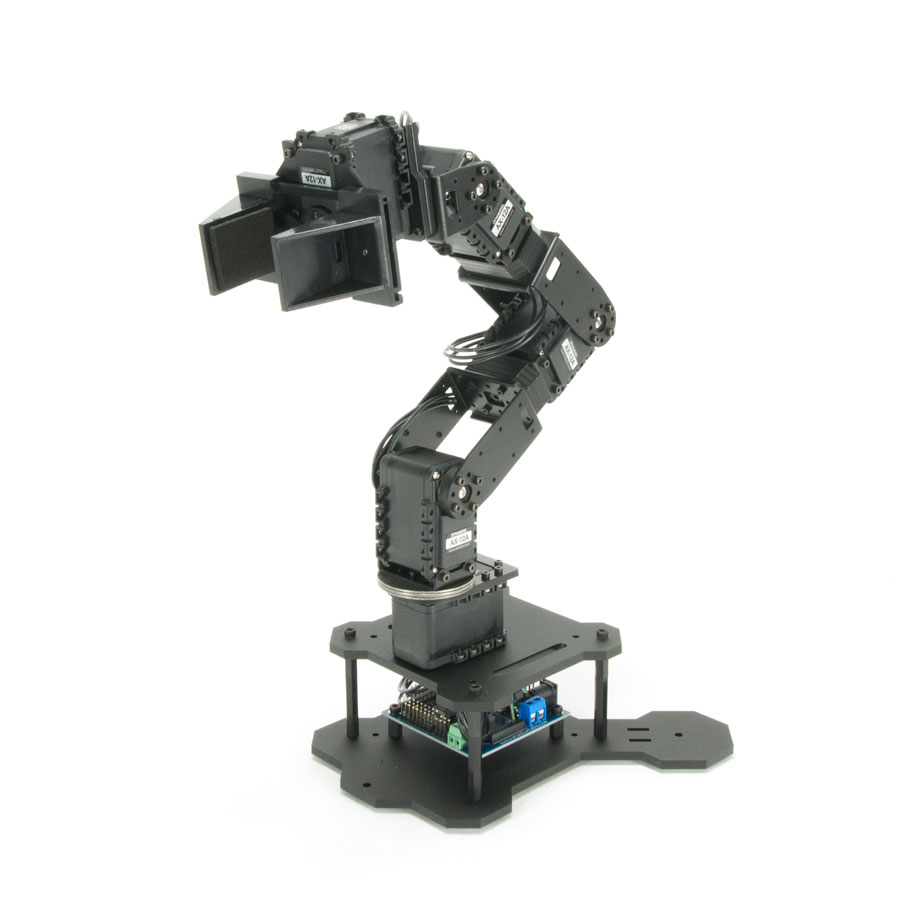

**Eslabones y las Articulaciones.**

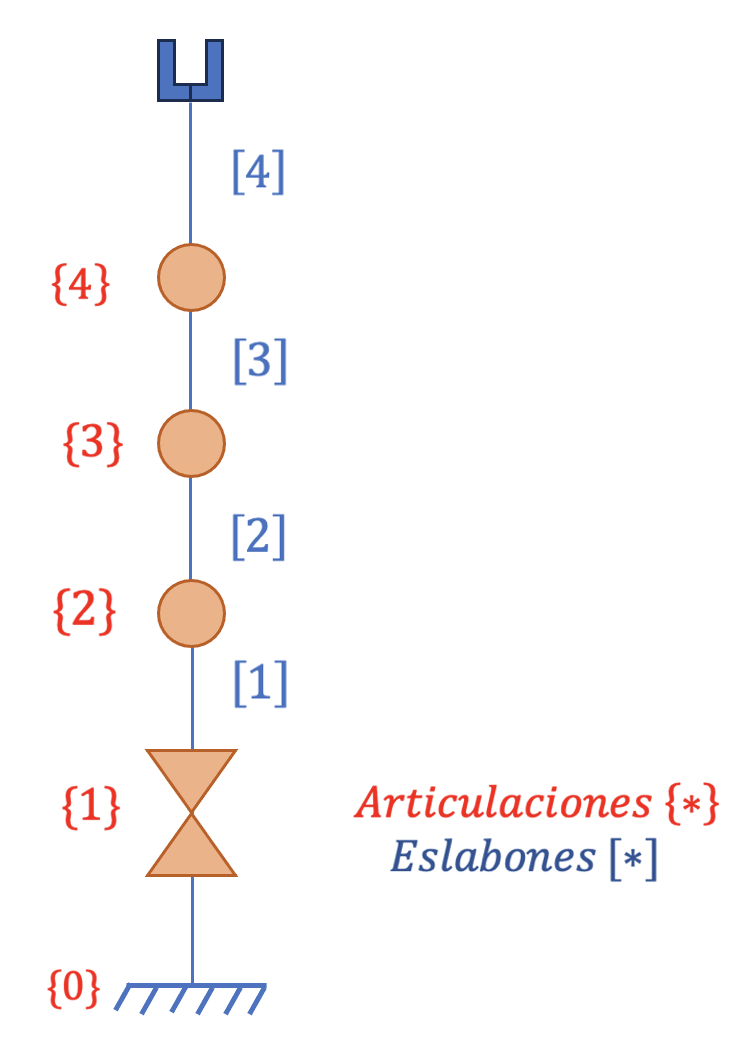

**Sistemas de Referencia según la Convención DHstd.**

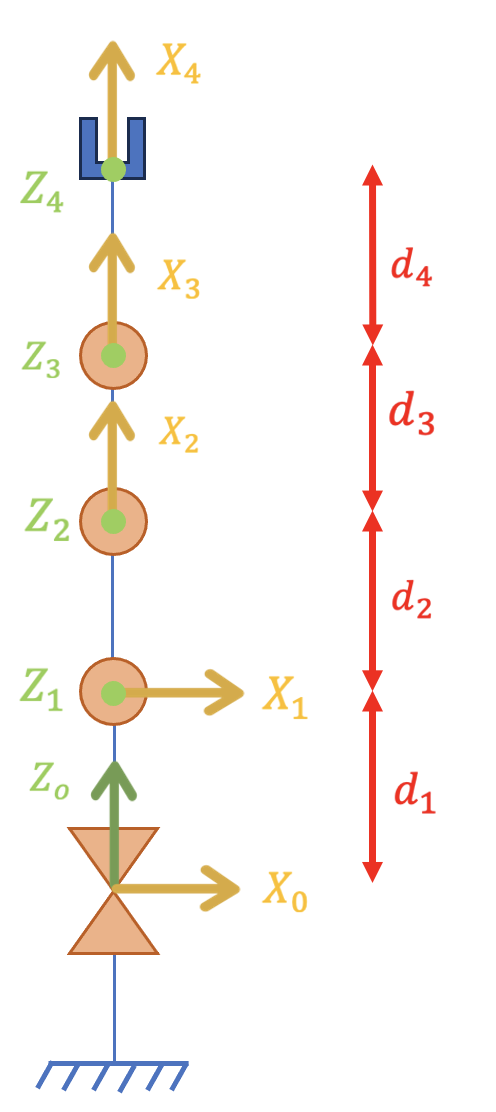

**Parámetros de acuerdo con la Convención DHstd.**


$$\begin{array}{||c|c|c|c|c|}
\hline
Link \space (i) & \theta_{i} & d_{i} & \alpha_{i} & a_{i} & Offset\\ 
\hline
1 &  q_{1} & 152.05 & \frac{\pi}{2} & 0 & 0 \\
\hline
2 & q_{2} & 0 & 0 & 136.82 & \frac{\pi}{2} \\
\hline
3 & q_{3} & 0 & 0 & 74.12 & 0 \\
\hline
4 & q_{4} & 0 & 0 & 108.4 & 0 \\
\hline
\end{array}$$


% Definición de los parámetros del robot
l_1 = 152.05; 
l_2 = 136.82; 
l_3 = 74.12;
l_4 = 108.4;

% Creación de un objeto de enlace para cada Articulación
L(1) = Link('revolute', 'qlim', [0 pi], 'd', l_1, 'a', 0, 'alpha', pi/2);
L(2) = Link('revolute', 'qlim', [0 pi], 'd', 0, 'a', l_2, 'alpha', 0);
L(3) = Link('revolute', 'qlim', [0 pi], 'd', 0, 'a', l_3, 'alpha', 0);
L(4) = Link('revolute', 'qlim', [0 pi], 'd', 0, 'a', l_4, 'alpha', 0);

% Creación del Objeto de Robot Serial
ROBOT = SerialLink(L, 'name', 'Robot')

 
ROBOT = 
 
Robot:: 4 axis, RRRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|     152.05|          0|     1.5708|          0|
|  2|         q2|          0|     136.82|          0|          0|
|  3|         q3|          0|      74.12|          0|          0|
|  4|         q4|          0|      108.4|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



% Definición de la Herramienta (Tool) del Robot
ROBOT.tool = trotx(0) * transl(0, 0, 0)

 
ROBOT = 
 
Robot:: 4 axis, RRRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|     152.05|          0|     1.5708|          0|
|  2|         q2|          0|     136.82|          0|          0|
|  3|         q3|          0|      74.12|          0|          0|
|  4|         q4|          0|      108.4|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


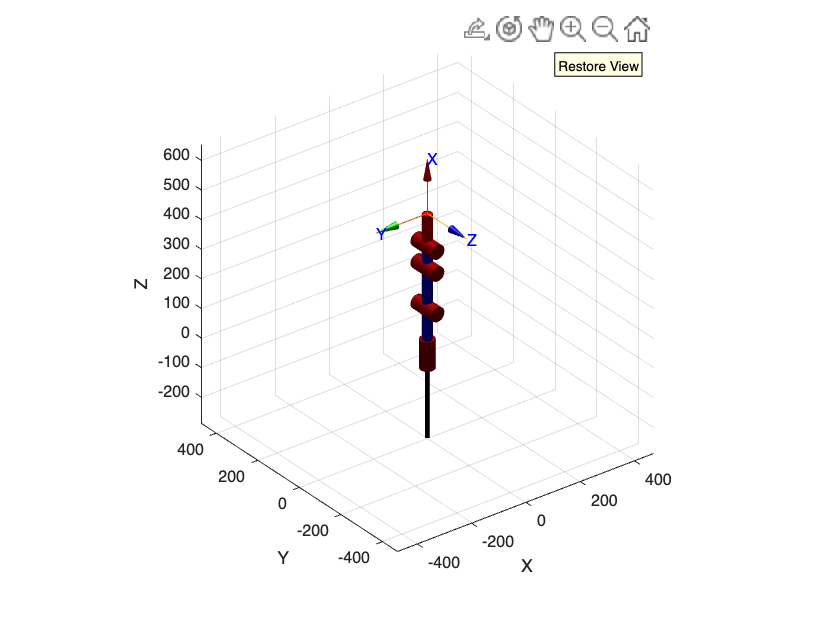


% Visualización del Robot en la Configuración Inicial
ROBOT.plot([0 pi/2 0 0], 'notiles', 'noname');

% Establecer Límites de Visualización
xlim([-471 471])
ylim([-471 471])
zlim([-288 655])